Rp=1;Rs=40;T=0.001;
wp1=0.4*pi;wp2=0.6*pi;
ws1=0.2*pi;ws2=0.8*pi;
wp3=(2/T)*tan(wp1/2);wp4=(2/T)*tan(wp2/2);
ws3=(2/T)*tan(ws1/2);ws4=(2/T)*tan(ws2/2);
wp=[wp3,wp4];ws=[ws3,ws4];
[n,wn]=cheb1ord(wp,ws,Rp,Rs,'s');
[z,p,k]=cheb1ap(n,Rp);
[b,a]=zp2tf(z,p,k);
w0=sqrt(wp3*wp4);
Bw=wp4-wp3;
[b1,a1]=lp2bp(b,a,w0,Bw);
[bz,az]=bilinear(b1,a1,1/T);

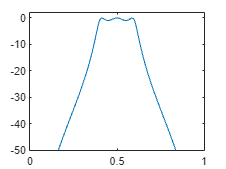

[db,mag,pha,grd,w]=freqz_m(bz,az);
plot(w/pi,db);axis([0,1,-50,2]);